a = 1 + mod(137,3);

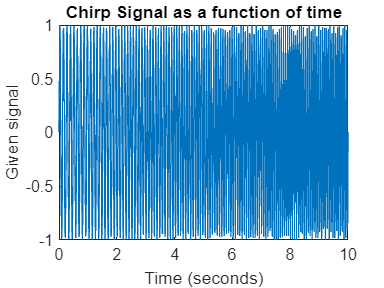

%Q1)
f = linspace(2+(2*a),3+(3*a),1000);
t = linspace(0,10,1000);
x = sin(2*pi*f.*t);
figure;
plot(t,x);
xlabel('Time (seconds)')
ylabel('Given signal')
title('Chirp Signal as a function of time')

%sound(x)

figure;
t = 0:0.01:10;
n = 0:999;
fs = 100;
x = sin(2*pi*f.*n/fs);
z = fft(x)

z =    0.9424 + 0.0000i   0.9427 - 0.0018i   0.9435 - 0.0036i   0.9449 - 0.0055i   0.9468 - 0.0073i   0.9493 - 0.0091i   0.9523 - 0.0110i   0.9559 - 0.0128i   0.9601 - 0.0147i   0.9649 - 0.0165i   0.9702 - 0.0184i   0.9762 - 0.0202i   0.9828 - 0.0221i   0.9900 - 0.0240i   0.9978 - 0.0259i   1.0064 - 0.0278i   1.0156 - 0.0298i   1.0255 - 0.0317i   1.0362 - 0.0337i   1.0476 - 0.0356i   1.0598 - 0.0376i   1.0728 - 0.0397i   1.0866 - 0.0417i   1.1014 - 0.0438i   1.1170 - 0.0459i   1.1336 - 0.0480i   1.1513 - 0.0502i   1.1699 - 0.0524i   1.1897 - 0.0546i   1.2107 - 0.0569i   1.2329 - 0.0592i   1.2563 - 0.0616i   1.2812 - 0.0640i   1.3075 - 0.0665i   1.3354 - 0.0691i   1.3649 - 0.0717i   1.3961 - 0.0744i   1.4293 - 0.0772i   1.4644 - 0.0801i   1.5016 - 0.0831i   1.5412 - 0.0863i   1.5832 - 0.0895i   1.6278 - 0.0929i   1.6754 - 0.0965i   1.7260 - 0.1003i   1.7800 - 0.1043i   1.8377 - 0.1085i   1.8993 - 0.1131i   1.9653 - 0.1179i   2.0361 - 0.1232i


% f = (0:length(y)-1)*100/length(y);
f2 = (0:999)*fs/1000 

f2 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


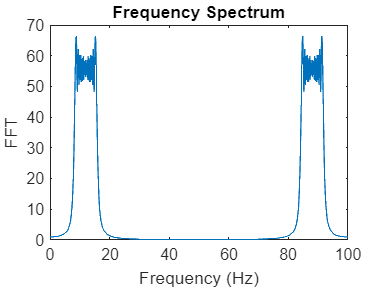

plot(f2,abs(z))
xlabel('Frequency (Hz)')
ylabel('FFT')
title('Frequency Spectrum')

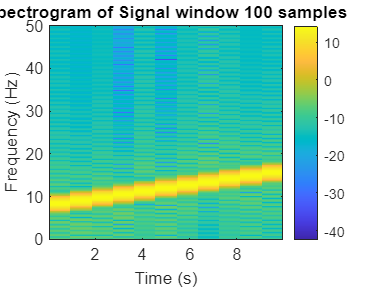

%Spectrogram
figure;
y=x;
% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 10*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
%colormap(jet);  % Choose a colormap (optional)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal window 100 samples');
colorbar;  % Display a colorbar showing the magnitude in dB

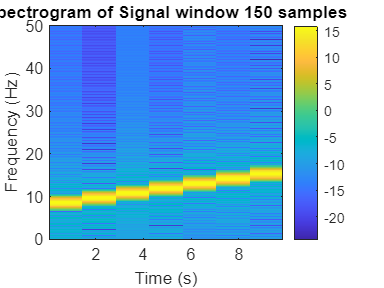

figure;
y=x;
% Step 2: Define spectrogram parameters
windowSize = 150;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 10*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
% colormap(jet);  % Choose a colormap (optional)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal window 150 samples');
colorbar;  % Display a colorbar showing the magnitude in dB

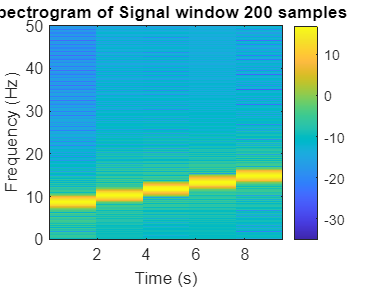

figure;
y=x;
% Step 2: Define spectrogram parameters
windowSize = 200;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 10*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
% colormap(jet);  % Choose a colormap (optional)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal window 200 samples');
colorbar;  % Display a colorbar showing the magnitude in dB

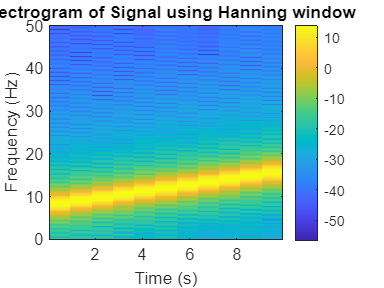

figure;
y=x;
% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hanning(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 10*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
% colormap(jet);  % Choose a colormap (optional)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal using Hanning window');
colorbar;  % Display a colorbar showing the magnitude in dB

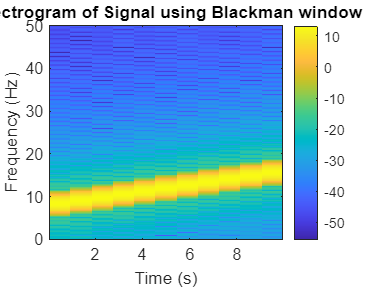

figure;
y=x;
% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, blackman(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 10*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
% colormap(jet);  % Choose a colormap (optional)
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal using Blackman window');
colorbar;  % Display a colorbar showing the magnitude in dB

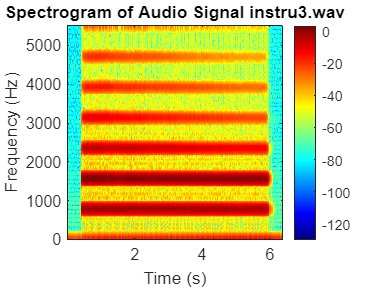

%Q2
%1
%Spectrogram
figure;
% Step 1: Read the audio file
audioFilePath = 'instru3.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap,nfft,fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 20*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Audio Signal instru3.wav');
colorbar;  % Display a colorbar showing the magnitude in dB
colormap('jet');

%fundamental pitch: around 1575Hz

% Step 2: Compute the FFT of the audio signal
N = length(y);  % Length of the audio signal
Y = fft(y);     % Compute the FFT

% Step 3: Find the fundamental frequency
frequencies = (0:N-1)*(fs/N);  % Frequency axis
magnitude = 20*log10(abs(Y));            % Magnitude of FFT
[~, idx] = max(magnitude(1:N/2+1));  % Find the index of the maximum magnitude
fundamentalFrequency = frequencies(idx);  % Fundamental frequency in Hz

% Display the results
fprintf('Fundamental Frequency: %.2f Hz\n', fundamentalFrequency);

Fundamental Frequency: 1566.24 Hz


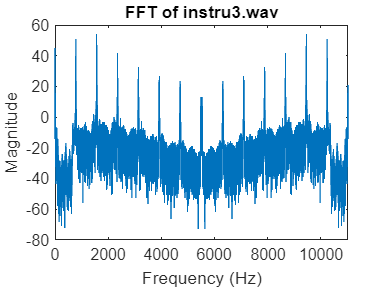

figure;
% plot the FFT
plot(frequencies, magnitude);
title('FFT of instru3.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

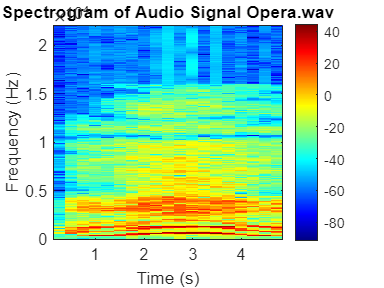

%Spectrogram
figure;
% Step 1: Read the audio file
audioFilePath = 'Opera.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Define spectrogram parameters
windowSize = 22000;  % Size of the analysis window (e.g., 256 samples)
overlap = 11000;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 20*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Audio Signal Opera.wav');
colorbar; 
colormap('jet')% Display a colorbar showing the magnitude in dB

%Q3)%Spectrogram
figure;
% Step 1: Read the audio file
audioFilePath = 'rv.mp4';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% audiowrite('rv_new.wav',y,4000);
% [y,fs] = audioread('rv_new.wav');

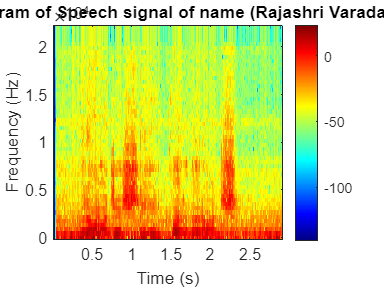

% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 50;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 100;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap, nfft, fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 20*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Speech signal of name (Rajashri Varadaraj)');
colorbar; 
colormap('jet')% Display a colorbar showing the magnitude in dB